syms x1 x2 x3 x4 u
% parametros del sistema
ma=0.6; % masa brazo [kg]
mp=0.2; % masa pendulo [kg]
la=1.1600e-1; % largo del brazo [m]
lp=3.0001e-1; % largo del pendulo [m]
j0=(ma*la^2)/3; %inercia brazo [kg m^2]
g=9.8;  % gravedad [m/s^-2]
j1=(mp*lp^2)/3; % inercia pendulo [kg m^2]
T=0.05;% tiempo de muestreo

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% x1: angulo del brazo (\phi)
% x2: velocidad angular del brazo (\dot\phi)
% x3: angulo del pendulo (\theta)  <- ESTADO NO LINEAL
% x4: velocidad angular del pendulo (\dot\theta)
% u: torque del motor 
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% sistema no lineal pendulo
a1=((ma+mp)/3)*la^2;  %alfa
a2=(mp*lp^2)/3;       %beta
a3=(mp*la*lp)/2;      %lambda
a4=(mp*g*lp)/2;       %delta
den=((a1*a2)-a3^2)+((a2^2+a3^2)*sin(x3)^2);

% campo vectorial
f1=x2;
f2=((a2*a3*(sin(x3)^2-1)*sin(x3)*x2^2)-...
    (2*a2^2*cos(x3)*sin(x3)*x2*x4)+(a2*a3*sin(x3)*x4^2)-...
    (a3*a4*cos(x3)*sin(x3))+(a2*u))/den;
f3=x4;
f4=((a2*(a1+a2*sin(x3)^2)*cos(x3)*sin(x3)*x2^2)+...
    (2*a2*a3*(1-sin(x3)^2)*sin(x3)*x2*x4)-...
    (a3^2*cos(x3)*sin(x3)*x4^2)+(a4*(a1+a2*sin(x3)^2)*sin(x3))-...
    (a3*cos(x3)*u))/den;

% Jacobiano simbólico
As=[diff(f1,x1) diff(f1,x2) diff(f1,x3) diff(f1,x4);...
    diff(f2,x1) diff(f2,x2) diff(f2,x3) diff(f2,x4);...
    diff(f3,x1) diff(f3,x2) diff(f3,x3) diff(f3,x4);...
    diff(f4,x1) diff(f4,x2) diff(f4,x3) diff(f4,x4)];

Bs=[diff(f1,u);diff(f2,u);diff(f3,u);diff(f4,u)];

C=[1 0 0 0];
D=[0];

% Ampliar A y B para acción integral
Aa = [As, zeros(4,1); -C, 0];
Bb = [Bs; 0];

%% Parámetros del controlador
zeta = 0.8;
tsdes = 2;
wn = 4.6 / (zeta * tsdes);
sistReferencia = tf([0 0 1],[1 2*zeta*wn wn^2]);
polosz = [pole(sistReferencia)' -0.3 -6 -5];

%% GAIN SCHEDULING BASADO EN EL ÁNGULO DEL PÉNDULO (x3 = theta)
% Cambiamos phi_vector por theta_vector
theta_vector = deg2rad(-50:1:50);  % Rango amplio del ángulo del péndulo
Ka = zeros(length(theta_vector), 5);  % matriz de ganancias

fprintf('Calculando ganancias para %d puntos de operación...\n', length(theta_vector));

Calculando ganancias para 101 puntos de operación...



for i = 1:length(theta_vector)
    theta_i = theta_vector(i);
    
    % Estado de equilibrio
    x1ss = 0;        % brazo en posición inicial
    x2ss = 0;        % velocidad brazo = 0
    x3ss = theta_i;  % ángulo del péndulo (variable de scheduling)
    x4ss = 0;        % velocidad péndulo = 0

    % Entrada de equilibrio
    uss = (3*g*la*mp*sin(2*x3ss))/8;

    % Evaluar matrices linealizadas
    A_num = double(subs(Aa, [x1, x2, x3, x4, u], [x1ss, x2ss, x3ss, x4ss, uss]));
    B_num = double(subs(Bb, [x1, x2, x3, x4, u], [x1ss, x2ss, x3ss, x4ss, uss]));

    % Verificar controlabilidad
    if rank(ctrb(A_num, B_num)) == size(A_num,1)
        Ka(i,:) = acker(A_num, B_num, polosz);
    else
        warning("Sistema no controlable para theta = %.2f rad (%.1f°)", theta_i, rad2deg(theta_i));
        Ka(i,:) = Ka(max(1,i-1),:);  % usar ganancia anterior si no es controlable
    end
    
    % Mostrar progreso
    if mod(i,5) == 0
        fprintf('Completado: %d/%d\n', i, length(theta_vector));
    end
end

Completado: 5/101
Completado: 10/101
Completado: 15/101
Completado: 20/101
Completado: 25/101
Completado: 30/101
Completado: 35/101
Completado: 40/101
Completado: 45/101
Completado: 50/101
Completado: 55/101
Completado: 60/101
Completado: 65/101
Completado: 70/101
Completado: 75/101
Completado: 80/101
Completado: 85/101
Completado: 90/101
Completado: 95/101
Completado: 100/101



%% Separación de ganancias individuales
K1 = Ka(:,1);  % asociado a x1 (phi)
K2 = Ka(:,2);  % asociado a x2 (dphi)
K3 = Ka(:,3);  % asociado a x3 (theta) - ¡ESTA ES LA VARIABLE DE SCHEDULING!
K4 = Ka(:,4);  % asociado a x4 (dtheta)
K5 = Ka(:,5);  % asociado al integrador

%% Ajuste polinomial de cada ganancia para interpolación
% Usamos grado 6 para capturar mejor la no linealidad
grado_poly = 6;
polk1 = polyfit(theta_vector, K1, grado_poly);
polk2 = polyfit(theta_vector, K2, grado_poly);
polk3 = polyfit(theta_vector, K3, grado_poly);
polk4 = polyfit(theta_vector, K4, grado_poly);
polk5 = polyfit(theta_vector, K5, grado_poly);


%% Control pendulo de Furuta en CoppeliaSim
% Se recomienda que sea en un archivo .m y no en un liveScript
% por la velocidad de ejecución
% A. Pantoja, Departamento de Electrónica, Universidad de Nariño
clear estados control controlmed
%clear all
close all
%% Inicialización de objeto CoppeliaSim y sincronización con planta 
vrep=remApi('remoteApi');

Note: always make sure you use the corresponding remoteApi library
(i.e. 32bit Matlab will not work with 64bit remoteApi, and vice-versa)


vrep.simxFinish(-1);
clientID=vrep.simxStart('127.0.0.1',19997,true,true,5000,5)

clientID = 0

r = 180*pi/180; 
re= [];
ban = 0;
ban2 = 0;
b = 0;
sws = [];
%% Parámetros del controlador Swing-up
params.mp = mp;
params.lp = lp;
params.g = g;
params.k = 2.0;

if (clientID>-1)
    disp('connected to remote API Server');
    vrep.simxSynchronous(clientID,false);    % modo sincronización
    % Obtencion de handles de los objetos en la simulación 
    [~,motor]=vrep.simxGetObjectHandle(clientID,'motor',vrep.simx_opmode_blocking); %motor - pos brazo
    [~,sensor1]=vrep.simxGetObjectHandle(clientID,'Potenciometro',vrep.simx_opmode_blocking); %sensor pos péndulo
    [~,sensorvb]=vrep.simxGetObjectHandle(clientID,'rotating',vrep.simx_opmode_blocking); %sensor vel brazo
    [~,sensorvp]=vrep.simxGetObjectHandle(clientID,'pendulum',vrep.simx_opmode_blocking);%sensor vel pendulo
    % Primera lectura de sensores modo streaming
    [~,angb]=vrep.simxGetJointPosition(clientID,motor,vrep.simx_opmode_streaming);
    [~,angp]=vrep.simxGetJointPosition(clientID,sensor1,vrep.simx_opmode_streaming);
    [~,~,angularb]=vrep.simxGetObjectVelocity(clientID,sensorvb,vrep.simx_opmode_streaming);
    [~,~,angularp]=vrep.simxGetObjectVelocity(clientID,sensorvp,vrep.simx_opmode_streaming);
    [~,torqm]=vrep.simxGetJointForce(clientID,motor,vrep.simx_opmode_streaming);
    vrep.simxPauseSimulation(clientID,vrep.simx_opmode_oneshot);    %pausa simulación
    pause(2);
 %% Inicialización de variables   
    % refv=[200*pi/180 180*pi/180 100*pi/180]; % Referencias
    % ref=refv(1);
    %ref=90*pi/180;
    Tsim=70;            % Tiempo total de la simulación
    Ts=0.1;               % Periodo de muestreo
    Ns=round(Tsim/Ts);  % Número de periodos de muestreo que tendrá la simulación.
    e_ant=0;
    int_err=0;
 %% Main Control Cycle
    vrep.simxStartSimulation(clientID,vrep.simx_opmode_oneshot);
     for i=1:Ns
             tic % Inicia conteo de tiempo para asegugar muestreo
             %vrep.simxStartSimulation(clientID,vrep.simx_opmode_oneshot);
             %vrep.simxSynchronousTrigger(clientID);
         % letura de estados: x1=pos_brazo[rad], x2=pos_pend[rad], x3=vel_brazo[rad/s], x4=vel_pend[rad/s]
             [~,angb]=vrep.simxGetJointPosition(clientID,motor,vrep.simx_opmode_buffer); 
             g(i) = angb;
             angb = angb-floor(angb/(2*pi))*2*pi; % Lectura de 0 a 2*pi sin saltos por periodicidad
             
             [~,angp]=vrep.simxGetJointPosition(clientID,sensor1,vrep.simx_opmode_buffer);
             [~,~,angularb]=vrep.simxGetObjectVelocity(clientID,sensorvb,vrep.simx_opmode_buffer);
             [~,~,angularp]=vrep.simxGetObjectVelocity(clientID,sensorvp,vrep.simx_opmode_buffer);
             [~,torqm]=vrep.simxGetJointForce(clientID,motor,vrep.simx_opmode_buffer);
             
             % if angularb < -1000
             %    b = 1;
             % end
             % if angularb > 1000
             %    b = 0;
             % end
             % if b == 1
             %     angb = angb-2*pi;
             % end
             % Estados medidos en un vector
             x=[angb; angularb(3); angp; angularp(1)]; % estados medidos
            % Aproximacion trapezoidal de la integral de error
             e_act=r-angb; %error angulo del brazo
            
            % Cálculo del torque de control
            y = x(1);
            re(i) = r;   
            % Ganancias interpoladas según el ángulo del brazo (y)
            theta_sat = max(min(angp, max(theta_vector)), min(theta_vector));
            Kad_gs = [polyval(polk1, theta_sat), polyval(polk2, theta_sat), ...
                  polyval(polk3, theta_sat), polyval(polk4, theta_sat), ...
                  polyval(polk5, theta_sat)];
        
            hp(i) = abs(angp-floor(angp/(2*pi))*2*pi);
            if abs(angp-floor(angp/(2*pi))*2*pi) < deg2rad(25) || abs(angp-floor(angp/(2*pi))*2*pi) > deg2rad(335)  && abs(angularp(1)) < deg2rad(150) %&& angb >  deg2rad(50) 
                if ban == 0;
                    r = angb ;%+deg2rad(10);
                    ban = 1;
                    ki = 1;
                end
                ki = ki+1;
                if ki == 60
                    ban2 = 1;
                end
                % Salida medida: ángulo del brazo (phi)
                 e = r - y;              % Error
                 int_err = int_err + Ts * e;  % Integrador
                 u_c = -1.4*Kad_gs * [x; int_err];
                 sw = 1;
                 u_c = min(u_c, 0.8);
                 u_c = max(u_c, -0.8);
            else
                 ban = 0;
                 ban2 = 0;
                 u_c = 0.7*swing_up_energy_controller(x, params);
                 %u_c = 0.3*cos(i*0.25);
                 int_err = 0; % Resetear el integrador
                 sw = 0;
             end

            % Aplicación de torque a motor en CoppeliaSim
             if u_c>0
                vel=99; torqap=u_c;
             else
                vel=-99; torqap=-u_c;
             end
             vrep.simxSetJointForce(clientID,motor,torqap,vrep.simx_opmode_blocking);
             vrep.simxSetJointTargetVelocity(clientID,motor,vel,vrep.simx_opmode_blocking);
            % Almacenamiento de vectores y actualización de memoria
            sws(i) =sw;
            e_ant=e_act;
            control(i)=u_c;
            controlmed(i)=torqm;
            %control(i)=vf;
            estados(i,:)=x;

            % Cambio de referencia
            if ban2 == 1
                if i==round(30/Ts)
                    r=140*pi/180;
                elseif i==round(45/Ts)
                    r=50*pi/180;
                end
            end
            toc
            pause(max(Ts-toc, 0));  % Espera el tiempo para garantizar muestreo uniforme      
     end 
    vrep.simxStopSimulation(clientID,vrep.simx_opmode_blocking); % para simulación
    vrep.simxFinish(-1);
end

connected to remote API Server


Elapsed time is 0.138319 seconds.
Elapsed time is 0.103981 seconds.
Elapsed time is 0.090167 seconds.
Elapsed time is 0.096849 seconds.
Elapsed time is 0.122230 seconds.
Elapsed time is 0.069732 seconds.
Elapsed time is 0.095424 seconds.
Elapsed time is 0.104891 seconds.
Elapsed time is 0.087808 seconds.
Elapsed time is 0.082405 seconds.
Elapsed time is 0.089395 seconds.
Elapsed time is 0.083097 seconds.
Elapsed time is 0.093031 seconds.
Elapsed time is 0.085532 seconds.
Elapsed time is 0.078424 seconds.
Elapsed time is 0.087321 seconds.
Elapsed time is 0.080305 seconds.
Elapsed time is 0.090291 seconds.
Elapsed time is 0.082778 seconds.
Elapsed time is 0.093325 seconds.
Elapsed time is 0.084940 seconds.
Elapsed time is 0.092550 seconds.
Elapsed time is 0.085734 seconds.
Elapsed time is 0.078511 seconds.
Elapsed time is 0.085327 seconds.
Elapsed time is 0.092808 seconds.
Elapsed time is 0.081311 seconds.
Elapsed time is 0.107423 seconds.
Elapsed time is 0.090720 seconds.
Elapsed time i

vrep.delete();

## Gráficas

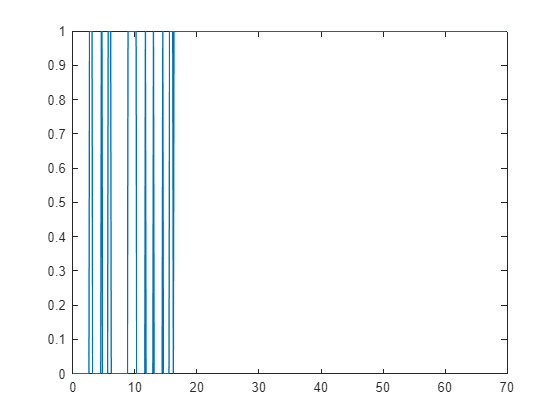

tdisc=0:Ts:Ns*Ts-Ts;
figure;
plot(tdisc, sws)

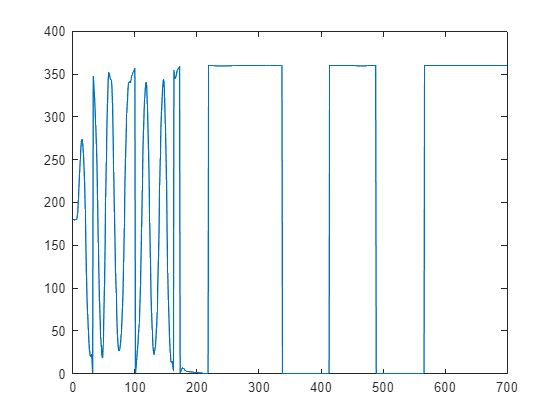

figure;
plot(hp*180/pi)

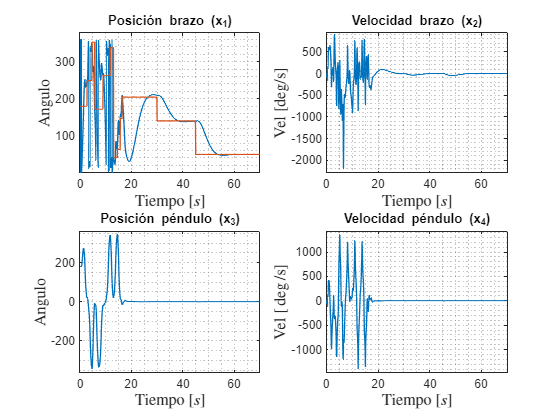


figure
subplot(2,2,1);
plot(tdisc,estados(:,1)*180/pi, 'LineWidth', 1);
hold on;
plot(tdisc, re*180/pi, 'LineWidth', 1);
grid minor;
ylabel("Angulo", "FontSize", 12, "FontWeight", "bold", "Interpreter", "latex");
xlabel("Tiempo $[s]$", "FontSize", 12, "FontWeight", "bold", "Interpreter", "latex");
title('Posición brazo (x_1)')
xlim([0, Ns*Ts])
ylim([1.05*min(estados(:,1)*180/pi), 1.05*max(estados(:,1)*180/pi)])

subplot(2,2,2);
plot(tdisc,estados(:,2)*180/pi, 'LineWidth', 1);
ylabel("Vel [deg/s]", "FontSize", 12, "FontWeight", "bold", "Interpreter", "latex");
xlabel("Tiempo $[s]$", "FontSize", 12, "FontWeight", "bold", "Interpreter", "latex");
title('Velocidad brazo (x_2)')
grid minor;
xlim([0, Ns*Ts])
ylim([1.05*min(estados(:,2)*180/pi), 1.05*max(estados(:,2)*180/pi)])

subplot(2,2,3);
plot(tdisc,estados(:,3)*180/pi, 'LineWidth', 1);
ylabel("Angulo", "FontSize", 12, "FontWeight", "bold", "Interpreter", "latex");
xlabel("Tiempo $[s]$", "FontSize", 12, "FontWeight", "bold", "Interpreter", "latex");
title('Posición péndulo (x_3)')
xlim([0, Ns*Ts])
ylim([1.05*min(estados(:,3)*180/pi), 1.05*max(estados(:,3)*180/pi)])
grid minor;

subplot(2,2,4);
plot(tdisc,estados(:,4)*180/pi, 'LineWidth', 1);
title('Velocidad péndulo (x_4)')
grid minor;
ylabel("Vel [$\deg$/s]", "FontSize", 12, "FontWeight", "bold", "Interpreter", "latex");
xlabel("Tiempo $[s]$", "FontSize", 12, "FontWeight", "bold", "Interpreter", "latex");
xlim([0, Ns*Ts])
ylim([1.05*min(estados(:,4)*180/pi), 1.05*max(estados(:,4)*180/pi)])

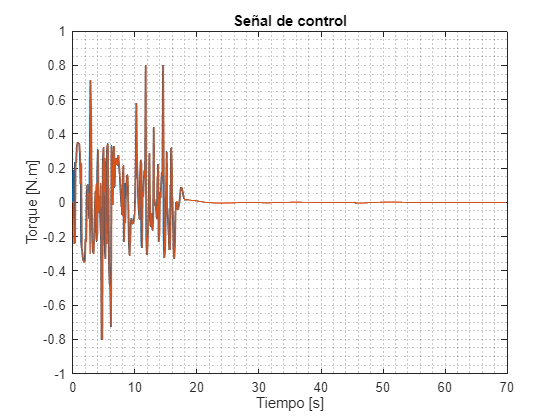


%%%%%%%%
figure
plot(tdisc,control, tdisc,-controlmed);
xlabel('Tiempo [s]');
ylabel('Torque [N.m]');
title('Señal de control')
grid minor;

ITAE y Energía

% Calcular el error
error_signal = ref - estados(:,1);
error_signal2 = 0-estados(:,3);
ITAE = trapz(tdisc, tdisc .* (abs(error_signal)+abs(error_signal2)));
disp(['ITAE: ', num2str(ITAE)]);

ITAE: 0       19.874794       39.749588      59.6243744       79.499176      99.3739777      119.248749       139.12355      158.998352      178.873123      198.747955      218.622696      238.497498      258.372253      278.247101      298.121918      317.996704       337.87146      357.746246      377.621033      397.495911      417.370605      437.245392      457.120178      476.994995      496.869843      516.744507      536.619385      556.494202      576.368896      596.243835      616.118591      635.993408      655.868347       675.74292      695.617676      715.492493      735.367371      755.242065      775.117065      794.991821      814.866577      834.741211      854.616089      874.490784      894.365601      914.240356      934.115112       953.98999      973.864746      993.739685      1013.61438      1033.48901      1053.36401      1073.23877      1093.11377       1112.9884      1132.86304      1152.73779      1172.61255      1192.48767      1212.36243      1232.23718 


y = estados(:, 1)*180/pi;
error_signal = abs(ref - y');
ITAE_LQR = trapz(tdisc, tdisc .* (error_signal+error_signal2));
ITAE = sum(tdisc.*error_signal)*Ts;
disp(['ITAE: ', num2str(ITAE)]);

ITAE: 246727.9219



% Calcular de la energía
ene_signal = control.^2;
ENE = trapz(tdisc, tdisc .* abs(ene_signal));
disp(['Energia: ', num2str(ENE)]); 

Energia: 8.3655


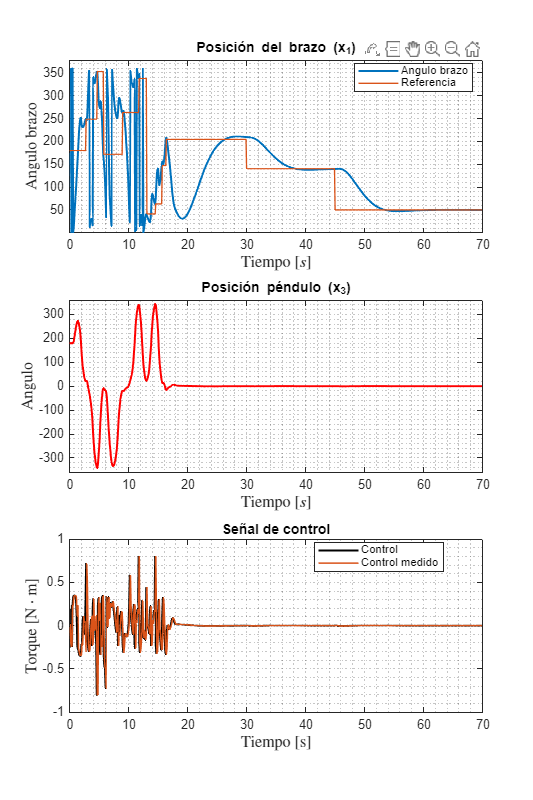

figure('Position', [100, 400, 1200, 1800]);  % [x, y, width, height]

subplot(3,1,1);
plot(tdisc, estados(:,1)*180/pi, 'LineWidth', 1.5);
hold on;
plot(tdisc, re*180/pi, 'LineWidth', 1);
grid minor;
ylabel("Angulo brazo", "FontSize", 12, "FontWeight", "bold", "Interpreter", "latex");
xlabel("Tiempo $[s]$", "FontSize", 12, "FontWeight", "bold", "Interpreter", "latex");
title("Posición del brazo (x_1)");
legend("Angulo brazo", "Referencia", "Location", "best");
xlim([0, Ns*Ts]);
ylim([1.05*min(estados(:,1)*180/pi), 1.05*max(estados(:,1)*180/pi)]);

subplot(3,1,2);
plot(tdisc, estados(:,3)*180/pi, 'r', 'LineWidth', 1.5);
ylabel("Angulo", "FontSize", 12, "FontWeight", "bold", "Interpreter", "latex");
xlabel("Tiempo $[s]$", "FontSize", 12, "FontWeight", "bold", "Interpreter", "latex");
title('Posición péndulo (x_3)')
xlim([0, Ns*Ts])
ylim([1.05*min(estados(:,3)*180/pi), 1.05*max(estados(:,3)*180/pi)])
grid minor;

subplot(3,1,3);
plot(tdisc, control, 'k', 'LineWidth', 1.5); hold on;
plot(tdisc, -controlmed, 'LineWidth', 1.2);
grid minor;
xlabel("Tiempo [s]", "FontSize", 12, "FontWeight", "bold", "Interpreter", "latex");
ylabel("Torque [N$\cdot$m]", "FontSize", 12, "FontWeight", "bold", "Interpreter", "latex");
title("Señal de control", "FontWeight", "bold", "Interpreter", "latex");
legend("Control", "Control medido", "Location", "best");
xlim([0, Ns*Ts]);